clear all, close all, clc

% Загрузка файла и создание матрицы H из созданного датасета

% loaded_data = load('..\H_dataset_test_8_1_1024.mat');
loaded_data = load('..\H_dataset_test_32_1_128.mat');

H_dataset = loaded_data.H_dataset;
[num_samples, timeslots, num_tx_antennas, num_subcarriers] = size(H_dataset)

num_samples = 3

timeslots = 10

num_tx_antennas = 32

num_subcarriers = 128


% Создание структуры для хранения метрик
metrics_results = struct();

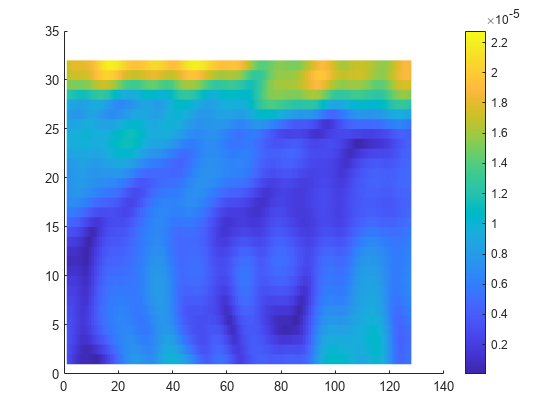

%% DFT методы

method_name = 'DFTmethod_1';

% truncation_factors = 2:2:(num_subcarriers);
truncation_factors = linspace(2, num_subcarriers, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

H_method = squeeze(H_dataset(1,1,:,:));
figure; clf; hold on;
surf(abs(squeeze(H_method)), 'EdgeColor', 'none'); colorbar;

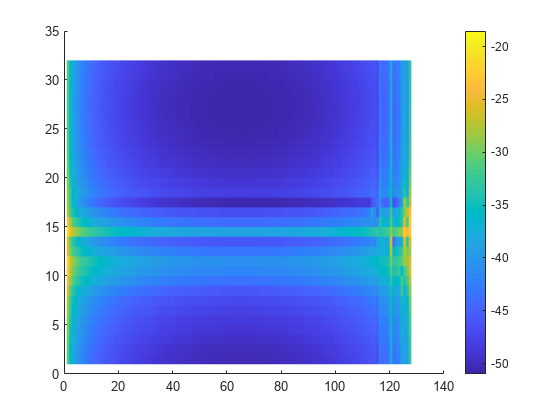

fft2_H_method = fft2(H_method);
figure; clf; hold on;
surf(10*log10(abs(squeeze(fft2_H_method))), 'EdgeColor', 'none'); colorbar;

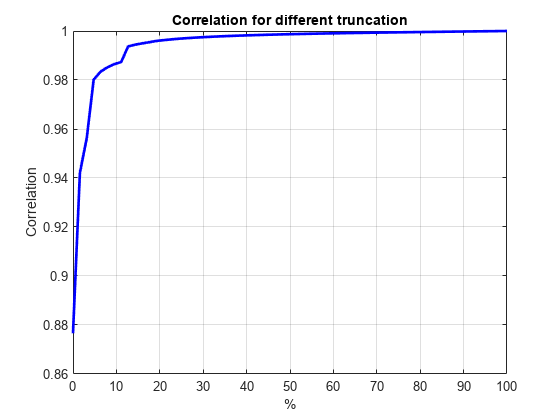


for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    midPoint = floor(num_subcarriers/2);
    lowerEdge = midPoint - (num_subcarriers-truncationFactor)/2 + 1;
    upperEdge = midPoint + (num_subcarriers-truncationFactor)/2;
    H_truncate_temp = fft2_H_method(:,[1:lowerEdge-1 upperEdge+1:end]);
    H_truncate = ifft2(H_truncate_temp);
    
    H_recover_temp = fft2(H_truncate);
    H_recover_zero = zeros(num_tx_antennas,num_subcarriers);
    H_recover_zero(:, [1:lowerEdge-1 upperEdge+1:end]) = H_recover_temp;
    H_recover(:, :) = ifft2(H_recover_zero);

    correlation_values(i) = hCorrelation(H_recover, H_method);
    nmse_values(i) = hNMSE(H_recover, H_method);
    % Рассчитываем процент для truncationFactor
    percent_truncation(i) = (truncationFactor - 2) / (num_subcarriers - 2) * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;


% Вывод результатов
% Correlation
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

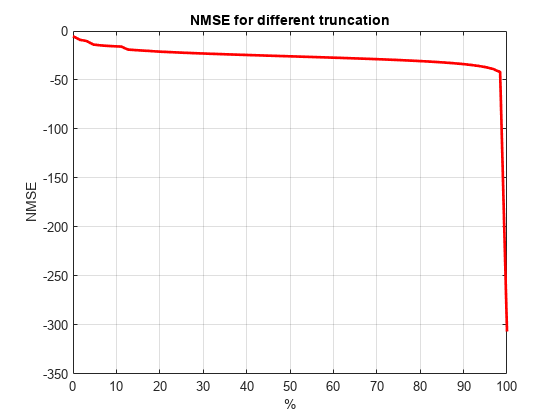


% NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

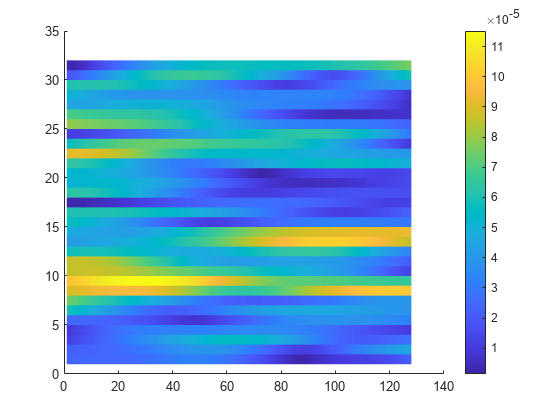


clear method_name H_method fft2_H_method truncation_factors percent_truncation correlation_values nmse_values
% для презентации
H_method = squeeze(H_dataset(2,1,:,:));
figure; clf; hold on;
surf(abs(squeeze(H_method)), 'EdgeColor', 'none'); colorbar;

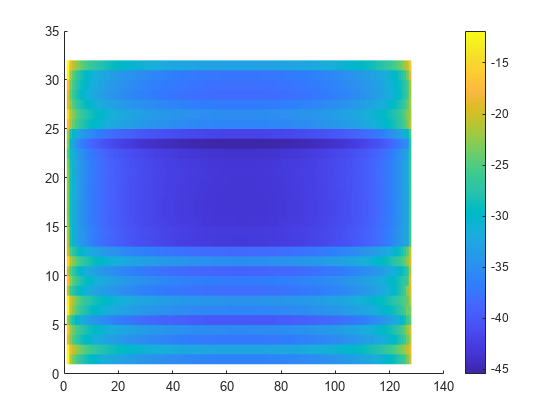


fft2_H_method = fft2(H_method);
figure; clf; hold on;
surf(10*log10(abs(squeeze(fft2_H_method))), 'EdgeColor', 'none'); colorbar;

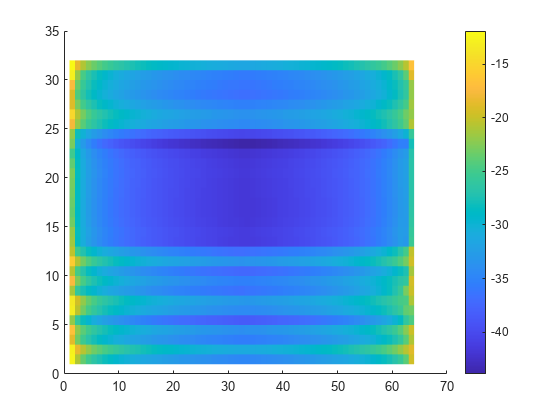


truncationFactor = 64;
midPoint = floor(num_subcarriers/2);
lowerEdge = midPoint - (num_subcarriers-truncationFactor)/2 + 1;
upperEdge = midPoint + (num_subcarriers-truncationFactor)/2;
H_truncate_temp = fft2_H_method(:,[1:lowerEdge-1 upperEdge+1:end]);
figure; clf; hold on;
surf(10*log10(abs(squeeze(H_truncate_temp))), 'EdgeColor', 'none'); colorbar;

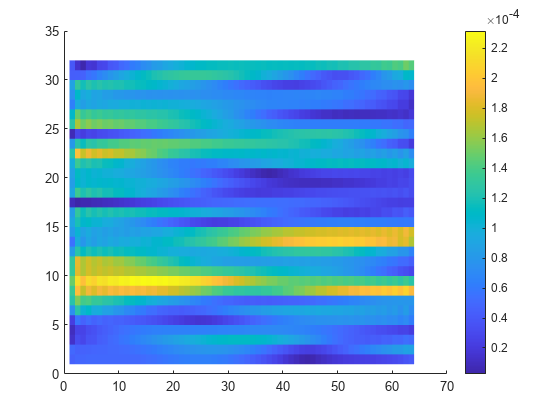

H_truncate = ifft2(H_truncate_temp);
figure; clf; hold on;
surf(abs(squeeze(H_truncate)), 'EdgeColor', 'none'); colorbar;

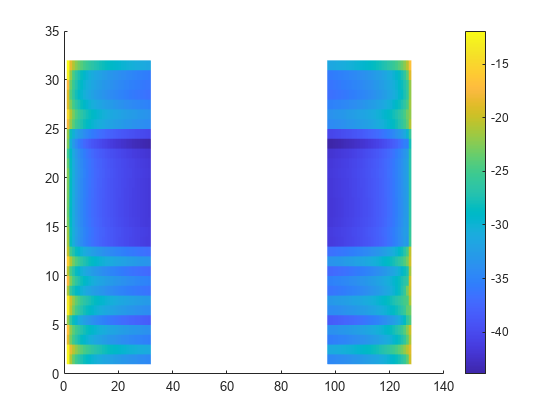


H_recover_temp = fft2(H_truncate);
H_recover_zero = zeros(num_tx_antennas,num_subcarriers);
H_recover_zero(:, [1:lowerEdge-1 upperEdge+1:end]) = H_recover_temp;

figure; clf; hold on;
surf(10*log10(abs(squeeze(H_recover_zero))), 'EdgeColor', 'none'); colorbar;

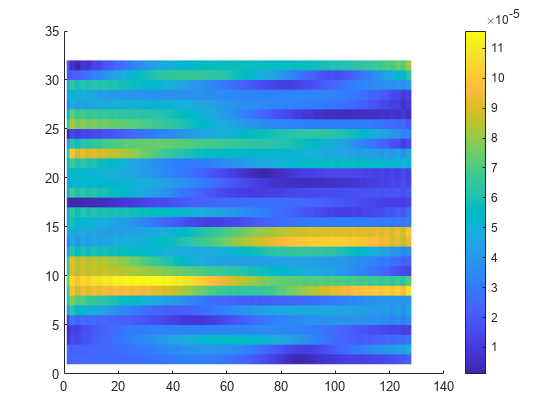


H_recover(:, :) = ifft2(H_recover_zero);

figure; clf; hold on;
surf(abs(squeeze(H_recover)), 'EdgeColor', 'none'); colorbar;



clear method_name H_method fft2_H_method truncation_factors percent_truncation correlation_values nmse_values



clear method_name H_method fft2_H_method truncation_factors percent_truncation correlation_values nmse_values



method_name = 'DFTmethod_2';

truncation_factors = linspace(0, 0.999, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

H_method = squeeze(H_dataset(1,1,:,:));

fft2_H_method = fft2(H_method);

% Обнуление всех малых коэффициентов и обратное преобразование

fft2_H_sort = sort(abs(fft2_H_method(:))); % Сортировка по величине

for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    thresh = fft2_H_sort(floor((1-truncationFactor)*length(fft2_H_sort)));
    ind = abs(fft2_H_method)>thresh; % Поиск малых индексов по пороговому
    H_truncate_temp = fft2_H_method.*ind; % Отсечение малых значений по маске
    
    H_truncate=ifft2(H_truncate_temp);

    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(H_truncate, H_method);
    nmse_values(i) = hNMSE(H_truncate, H_method);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = truncationFactor * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;


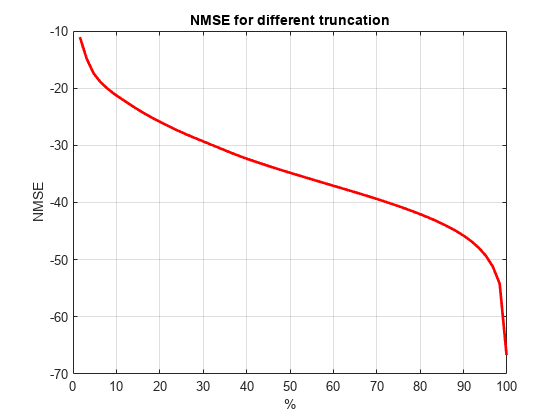

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

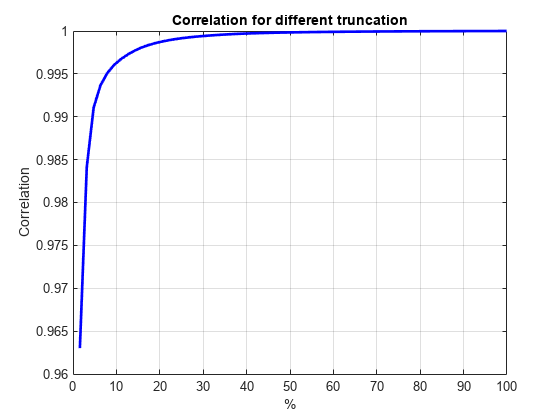

% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;


clear method_name H_method fft2_H_method truncation_factors percent_truncation correlation_values nmse_values

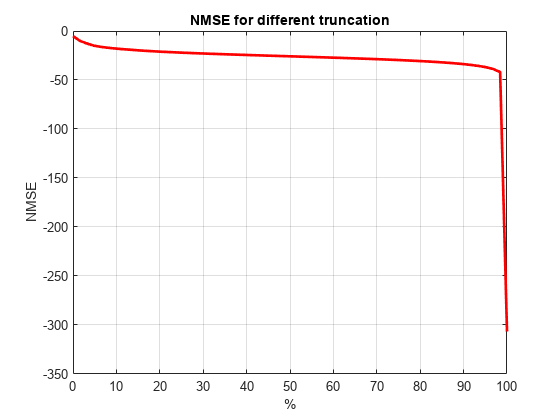

method_name = 'DFTmethod_3';

H_method = squeeze(H_dataset(1,1,:,:));

fft2_H_method = fft2(H_method);

truncation_factors = linspace(2, num_subcarriers, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);

    norms_sum = sum(abs(fft2_H_method(:,:)),1);
    [sorted_norms,sorted_index] = sort(norms_sum, "descend");
    select_index = sort(sorted_index(1:truncationFactor));
    % Создание новой матрицы c пороговым значением и её усечение
    H_truncate_temp = fft2_H_method(:,select_index);
    H_truncate = ifft2(H_truncate_temp);

    % Создание вектра позиций сохранённных элементов
    zero_vector = zeros(1, num_subcarriers);
    zero_vector(select_index) = 1;
    

    H_recover_temp = fft2(H_truncate);
    H_recover_zero = zeros(num_tx_antennas,num_subcarriers);

    fill_rows = zero_vector == 1;
    H_recover_zero(:, fill_rows) = H_recover_temp;
    H_recover(:, :) = ifft2(H_recover_zero);

    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(H_recover, H_method);
    nmse_values(i) = hNMSE(H_recover, H_method);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = (truncationFactor - 2) / (num_subcarriers - 2) * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

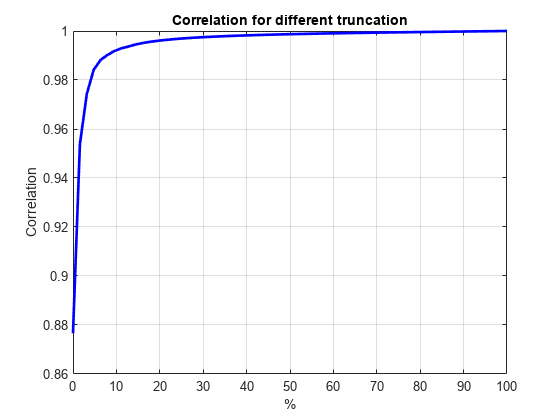


% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

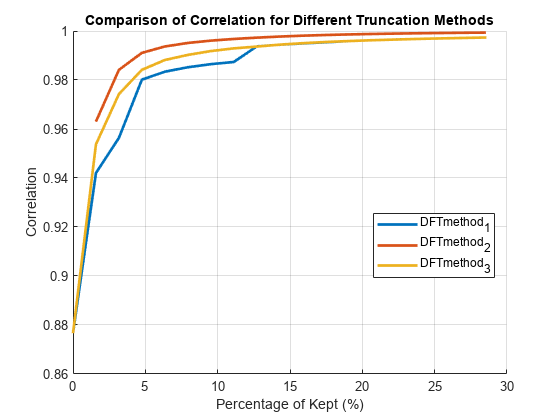


clear method_name H_method fft2_H_method truncation_factors percent_truncation correlation_values nmse_values

% Определение максимального процента для отображения
max_percent = 30; % Например, отображаем только до 50%

% Создание новой фигуры для общего графика корреляции
figure;
hold on;
% methods = fieldnames(metrics_results);
all_methods = fieldnames(metrics_results); % Получаем все имена методов
methods = all_methods(startsWith(all_methods, 'DFT')); % Выбираем только те, что начинаются с 'DFT'
% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    correlation_values = metrics_results.(method_name).correlation_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;

    % Построение графика для корреляции
    plot(percent_truncation(valid_indices), correlation_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('Correlation');
title('Comparison of Correlation for Different Truncation Methods');
grid on;
legend('Location', 'best');
% Ограничение оси x до максимального процента
xlim([0, max_percent]);

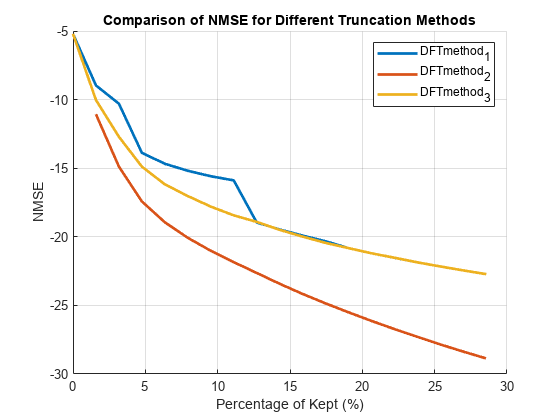


% Создание новой фигуры для общего графика NMSE
figure;
hold on;

% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    nmse_values = metrics_results.(method_name).nmse_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;
    
    % Построение графика для NMSE
    plot(percent_truncation(valid_indices), nmse_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('NMSE');
title('Comparison of NMSE for Different Truncation Methods');
grid on;
legend('Location', 'best');

% Ограничение оси x до максимального процента
xlim([0, max_percent]);

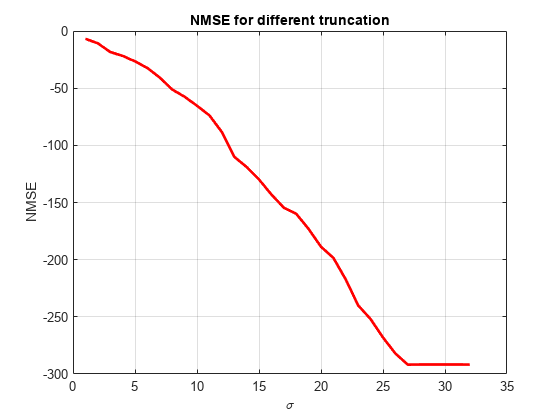


method_name = 'SVDmethod_1';

H_method = squeeze(H_dataset(1,1,:,:));
[U, S, V] = svd(H_method(:,:));

% Создание массивов для хранения значений корреляции и NMSE
truncation_factors = 1:num_tx_antennas; 
correlation_values = zeros(size(truncation_factors));
nmse_values = zeros(size(truncation_factors));

H_recover = zeros(length(truncation_factors), num_tx_antennas, num_subcarriers);

for i = 1:length(truncation_factors)
    r = truncation_factors(i);
    H_recover(i, :, :) = U(:, 1:r) * S(1:r, 1:r) * V(:, 1:r)'; 
    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(squeeze(H_recover(i,:,:)), H_method);
    nmse_values(i) = hNMSE(squeeze(H_recover(i,:,:)), H_method);
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(truncation_factors, nmse_values, 'r-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

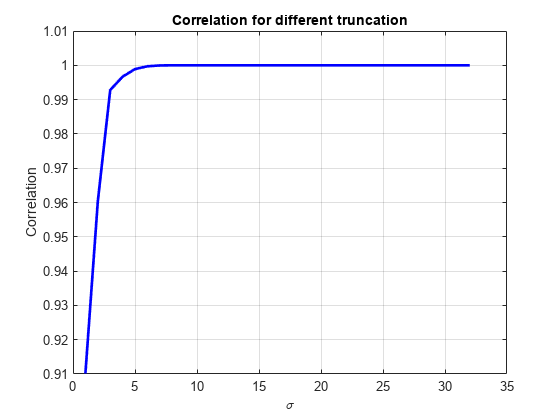


% Построение графика для корреляции
figure;
plot(truncation_factors, correlation_values, 'b-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

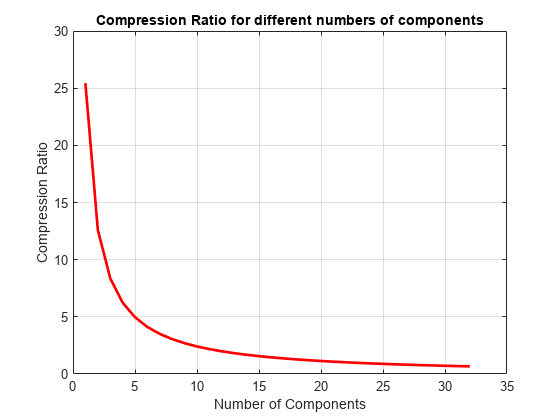

% Количество элементов в исходной матрице
original_elements = numel(H_method);

% Количество элементов для каждого r
compressed_elements = zeros(size(truncation_factors));
for i = 1:length(truncation_factors)
    r = truncation_factors(i);
    
    % Количество элементов для хранения сжатой матрицы
    num_elements = numel(U(:, 1:r)) + numel(S(1:r, 1:r)) + numel(V(:, 1:r)');
    compressed_elements(i) = num_elements;
end

% Во сколько раз происходит сжатие
compression_ratio = original_elements ./ compressed_elements;

% Построение графика
figure;
plot(truncation_factors, compression_ratio, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Compression Ratio');
title('Compression Ratio for different numbers of components');
grid on;

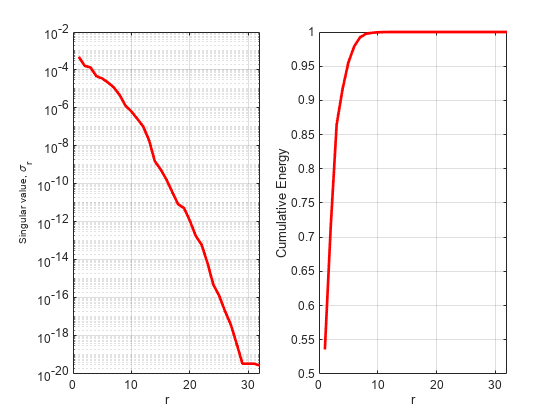

figure, subplot(1,2,1)
semilogy(diag(S),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Singular value, \sigma_r') 
subplot(1,2,2)
plot(cumsum(diag(S))/sum(diag(S)),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Cumulative Energy')

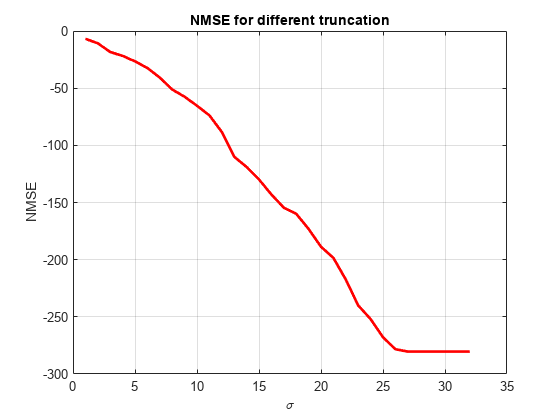

clear method_name H_method fft2_H_method H_recover U S V truncation_factors percent_truncation correlation_values nmse_values

method_name = 'SVDmethod_2';

H_method = squeeze(H_dataset(1,1,:,:));
fft2_H_method = fft2(H_method);
[U, S, V] = svd(fft2_H_method);

% Создание массивов для хранения значений корреляции и NMSE
truncation_factors = 1:num_tx_antennas; 
correlation_values = zeros(size(truncation_factors));
nmse_values = zeros(size(truncation_factors));

H_recover = zeros(length(truncation_factors), num_tx_antennas, num_subcarriers);

for i = 1:length(truncation_factors)
    r = truncation_factors(i);
    H_recover(i, :, :) = U(:, 1:r) * S(1:r, 1:r) * V(:, 1:r)';
    
    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(ifft2(squeeze(H_recover(i,:,:))), H_method);
    nmse_values(i) = hNMSE(ifft2(squeeze(H_recover(i,:,:))), H_method);
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(truncation_factors, nmse_values, 'r-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;


% Построение графика для корреляции
figure;
plot(truncation_factors, correlation_values, 'b-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;


% Количество элементов в исходной матрице
original_elements = numel(H_method);

% Количество элементов для каждого r
compressed_elements = zeros(size(truncation_factors));
for i = 1:length(truncation_factors)
    r = truncation_factors(i);
    
    % Количество элементов для хранения сжатой матрицы
    num_elements = numel(U(:, 1:r)) + numel(S(1:r, 1:r)) + numel(V(:, 1:r)');
    compressed_elements(i) = num_elements;
end

% Во сколько раз происходит сжатие
compression_ratio = original_elements ./ compressed_elements;

% Построение графика
figure;
plot(truncation_factors, compression_ratio, 'r-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Compression Ratio');
title('Compression Ratio for different numbers of components');
grid on;

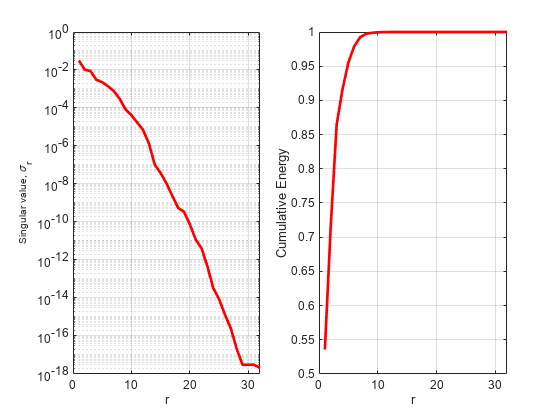


figure, subplot(1,2,1)
semilogy(diag(S),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Singular value, \sigma_r') 
subplot(1,2,2)
plot(cumsum(diag(S))/sum(diag(S)),'r-','LineWidth',2), grid on 
xlabel('r')
ylabel('Cumulative Energy')

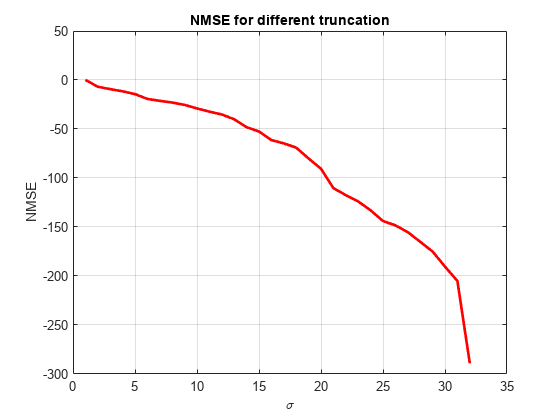


clear method_name H_method fft2_H_method H_recover U S V truncation_factors percent_truncation correlation_values nmse_values

method_name = 'SVDmethod_3';

H_method = squeeze(H_dataset(1,1,:,:));

% Создание массивов для хранения значений корреляции и NMSE
truncation_factors = 1:num_tx_antennas; 
correlation_values = zeros(size(truncation_factors));
nmse_values = zeros(size(truncation_factors));

H_recover = zeros(length(truncation_factors), num_tx_antennas, num_subcarriers);



for i = 1:length(truncation_factors)
    r = truncation_factors(i);
    % Разделение на реальную и мнимую части
    H_method_real = real(H_method);
    H_method_imag = imag(H_method);
    % Сжатие реальной части
    [U_real, S_real, V_real] = svd(H_method_real);
    comp_matrix_real = U_real(:, 1:r) * S_real(1:r, 1:r) * V_real(:, 1:r)';
    
    % Сжатие мнимой части
    [U_imag, S_imag, V_imag] = svd(H_method_imag);
    comp_matrix_imag = U_imag(:, 1:r) * S_imag(1:r, 1:r) * V_imag(:, 1:r)';
    
    % Объединение в комплексное число
    H_recover(i, :, :) = comp_matrix_real + 1i * comp_matrix_imag;

     % Сохранение значений метрик
    correlation_values(i) = hCorrelation(squeeze(H_recover(i,:,:)), H_method);
    nmse_values(i) = hNMSE(squeeze(H_recover(i,:,:)), H_method);
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(truncation_factors, nmse_values, 'r-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

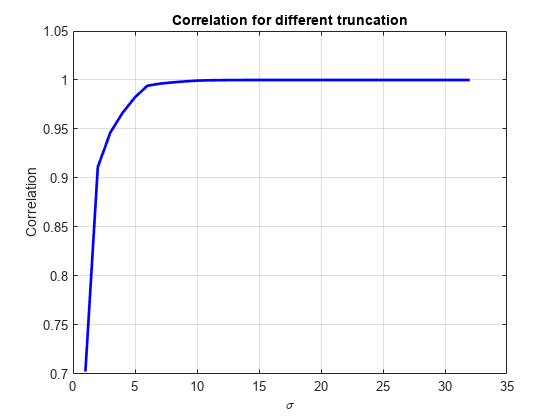


% Построение графика для корреляции
figure;
plot(truncation_factors, correlation_values, 'b-', 'LineWidth', 2);
xlabel('\sigma');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;


clear method_name H_method fft2_H_method H_recover U S V truncation_factors percent_truncation correlation_values nmse_values



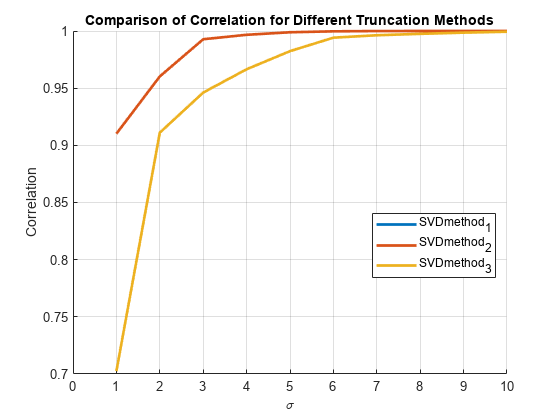

% Определение количества компонент для отображения
max_percent = 10; % Например, отображаем только до 30

% Создание новой фигуры для общего графика корреляции
figure;
hold on;
% methods = fieldnames(metrics_results);
all_methods = fieldnames(metrics_results); % Получаем все имена методов
methods = all_methods(startsWith(all_methods, 'SVD')); % Выбираем только те, что начинаются с 'SVD'
% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    truncation_factors = metrics_results.(method_name).truncation_factors;
    correlation_values = metrics_results.(method_name).correlation_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = truncation_factors <= max_percent;

    % Построение графика для корреляции
    plot(truncation_factors(valid_indices), correlation_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('\sigma');
ylabel('Correlation');
title('Comparison of Correlation for Different Truncation Methods');
grid on;
legend('Location', 'best');
% Ограничение оси x до максимального процента
xlim([0, max_percent]);

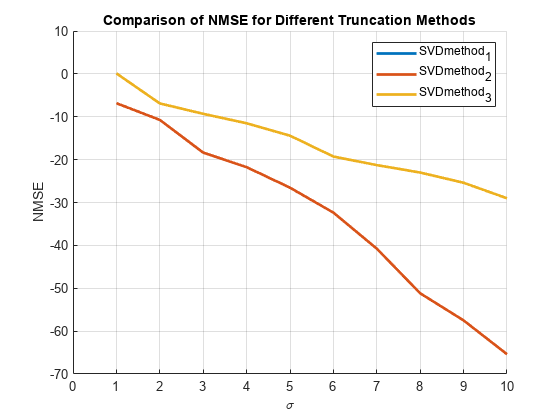


% Создание новой фигуры для общего графика NMSE
figure;
hold on;

% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    truncation_factors = metrics_results.(method_name).truncation_factors;
    nmse_values = metrics_results.(method_name).nmse_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = truncation_factors <= max_percent;
    
    % Построение графика для NMSE
    plot(truncation_factors(valid_indices), nmse_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('\sigma');
ylabel('NMSE');
title('Comparison of NMSE for Different Truncation Methods');
grid on;
legend('Location', 'best');

% Ограничение оси x до максимального процента
xlim([0, max_percent]);

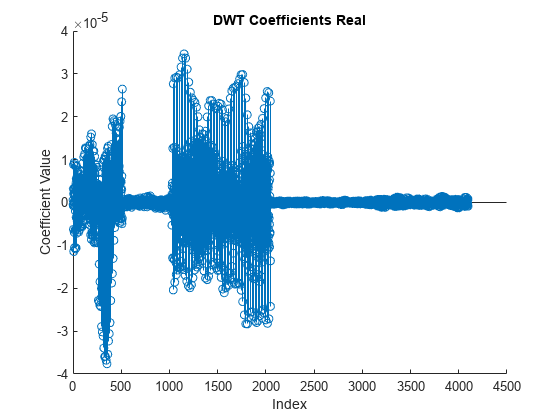

method_name = 'DWTmethod_1';

H_method = squeeze(H_dataset(1,1,:,:));

% Создание массивов для хранения значений корреляции и NMSE
truncation_factors = linspace(0, 0.999, 64); 
percent_truncation = zeros(size(truncation_factors));
correlation_values = zeros(size(truncation_factors));
nmse_values = zeros(size(truncation_factors));

H_recover = zeros(length(truncation_factors), num_tx_antennas, num_subcarriers);

% Получение действительной и мнимой частей матрицы H
real_part = real(H_method);
imag_part = imag(H_method);

% Вейвлет-сжатие для действительной части
[C_real, S_real] = wavedec2(real_part, 2, 'db1');
% Вейвлет-сжатие для мнимой части
[C_imag, S_imag] = wavedec2(imag_part, 2, 'db1');

figure; clf; hold on;
stem(C_real);
title('DWT Coefficients Real');
xlabel('Index');
ylabel('Coefficient Value');

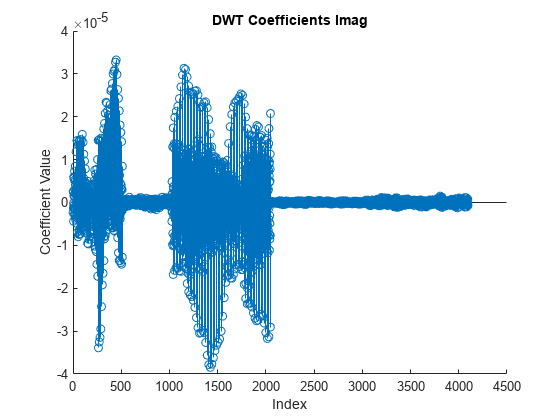

figure; clf; hold on;
stem(C_imag);
title('DWT Coefficients Imag');
xlabel('Index');
ylabel('Coefficient Value');

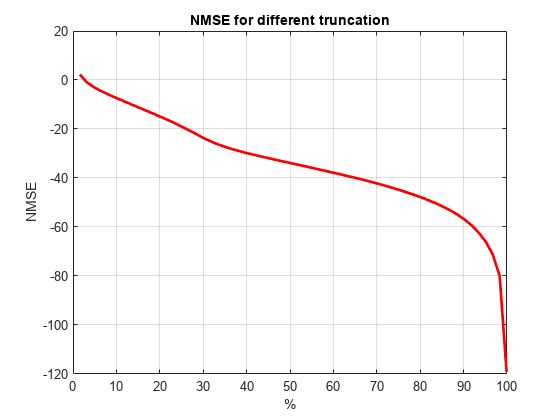



% Обработка действительной части
Csort_real = sort(abs(C_real(:))); % Сортировка по величине
Csort_imag = sort(abs(C_imag(:))); % Сортировка по величине

for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    thresh_real = Csort_real(floor((1-truncationFactor)*length(Csort_real)));
    ind_real = abs(C_real)>thresh_real; % Find small indices
    Cfilt_real = C_real.*ind_real; % Threshold small indices
    Arecon_real = waverec2(Cfilt_real, S_real, 'db1'); % Compressed image

    thresh_imag = Csort_imag(floor((1-truncationFactor)*length(Csort_imag)));
    ind_imag = abs(C_imag)>thresh_imag; % Find small indices
    Cfilt_imag = C_imag.*ind_imag; % Threshold small indices
    Arecon_imag = waverec2(Cfilt_imag, S_imag, 'db1'); % Compressed image

    H_recover(i, :, :) = Arecon_real + 1i*Arecon_imag;

    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(squeeze(H_recover(i, :, :)), H_method);
    nmse_values(i) = hNMSE(squeeze(H_recover(i, :, :)), H_method);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = truncationFactor * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

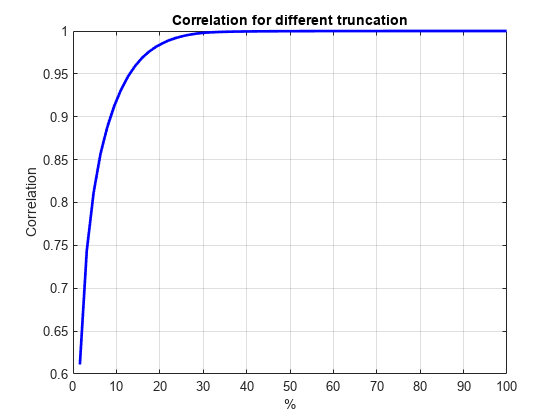


% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

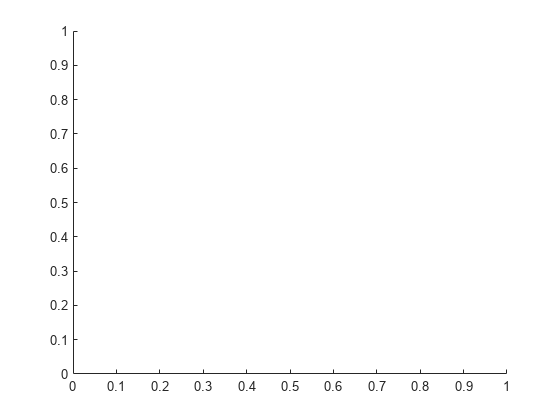

clear method_name H_method fft2_H_method H_recover U S V truncation_factors percent_truncation correlation_values nmse_values

method_name = 'DWTmethod_2';

H_method = squeeze(H_dataset(1,1,:,:));

% Создание массивов для хранения значений корреляции и NMSE
truncation_factors = linspace(0, 0.999, 64); 
percent_truncation = zeros(size(truncation_factors));
correlation_values = zeros(size(truncation_factors));
nmse_values = zeros(size(truncation_factors));

H_recover = zeros(length(truncation_factors), num_tx_antennas, num_subcarriers);

% Получаем модуль комплексной матрицы
H_method_modulus = abs(H_method);

% Вейвлет-сжатие
[C,S] = wavedec2(H_method_modulus, 2, 'db1');

Csort = sort(abs(C(:))); % Сортировка по величине

figure; clf; hold on;

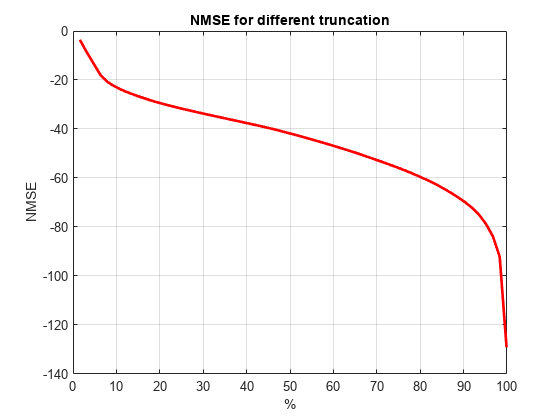


for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    thresh = Csort(floor((1-truncationFactor)*length(Csort)));
    ind = abs(C)>thresh; % Находим индексы малых значений
    Cfilt = C.*ind; % Пороговая фильтрация
    H_recover_modulus = waverec2(Cfilt,S,'db1'); % Восстановление сжатого изображения
    H_recover(i, :, :) = H_recover_modulus .* exp(1i * angle(H_method)); % Восстановление комплексных чисел
    
    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(squeeze(H_recover(i, :, :)), H_method);
    nmse_values(i) = hNMSE(squeeze(H_recover(i, :, :)), H_method);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = truncationFactor * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

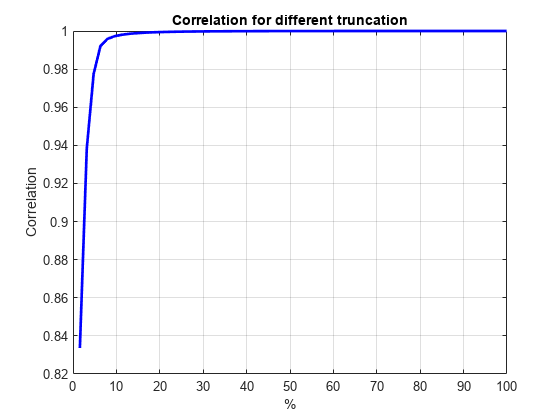


% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

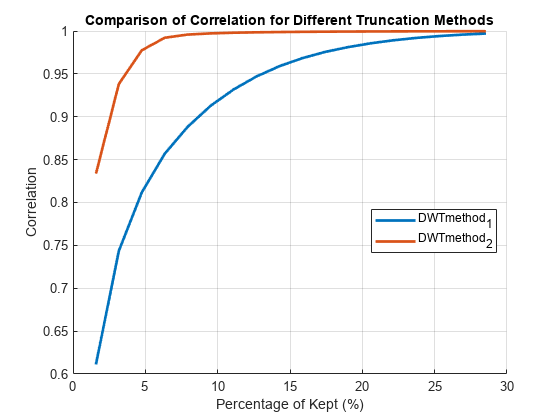


clear method_name H_method fft2_H_method H_recover U S V truncation_factors percent_truncation correlation_values nmse_values


% Определение максимального процента для отображения
max_percent = 30; % Например, отображаем только до 50%

% Создание новой фигуры для общего графика корреляции
figure;
hold on;
% methods = fieldnames(metrics_results);
all_methods = fieldnames(metrics_results); % Получаем все имена методов
methods = all_methods(startsWith(all_methods, 'DWT')); % Выбираем только те, что начинаются с 'DWT'
% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    correlation_values = metrics_results.(method_name).correlation_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;

    % Построение графика для корреляции
    plot(percent_truncation(valid_indices), correlation_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('Correlation');
title('Comparison of Correlation for Different Truncation Methods');
grid on;
legend('Location', 'best');
% Ограничение оси x до максимального процента
xlim([0, max_percent]);

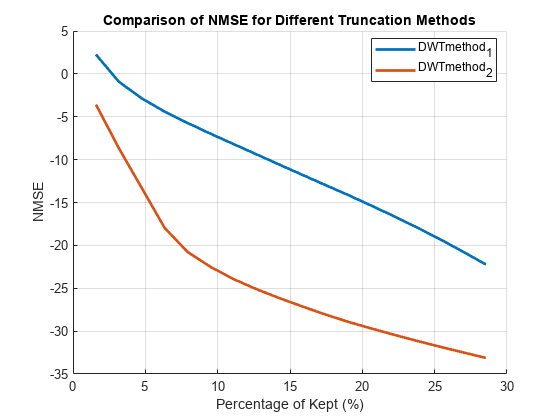


% Создание новой фигуры для общего графика NMSE
figure;
hold on;

% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    nmse_values = metrics_results.(method_name).nmse_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;
    
    % Построение графика для NMSE
    plot(percent_truncation(valid_indices), nmse_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('NMSE');
title('Comparison of NMSE for Different Truncation Methods');
grid on;
legend('Location', 'best');

% Ограничение оси x до максимального процента
xlim([0, max_percent]);

 Вспомогательные функции

function rho = hCorrelation(in,out)
% RHO = hCSICorrelation(X,Y) возвращает линейную корреляцию между X и Y.

n1 = sqrt(sum(conj(in).*in,'all'));
n2 = sqrt(sum(conj(out).*out,'all'));
aa = abs(sum(conj(in).*out,'all'));
rho = aa / (n1*n2);
end

function nmse = hNMSE(in,out)
% NMSE = helperNMSE(X,Y) возвращает нормализованную среднюю квадратичную ошибку (NMSE) между X и Y. 

mse = mean(abs(in-out).^2,'all');
nmse = 10*log10(mse / mean(abs(in).^2,'all'));
end